# Mobile Robot Short project support

Use this preliminary code as the basis to develop the comming Short Project

## Pose stimation code

Open: EKF_Pose_estimation.slx model.

See: Where2Find_Code.pdf file to learn how to acces to Pose_ estimation code and plotting results.

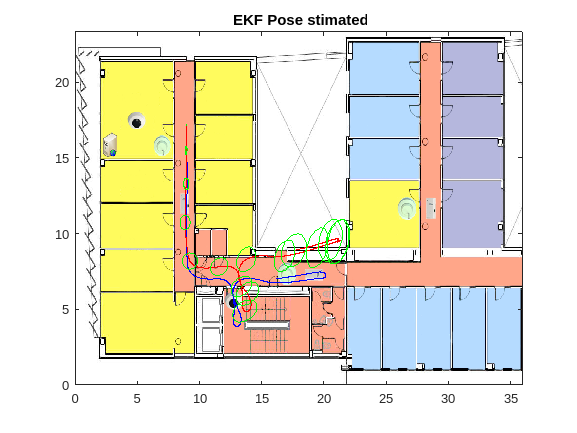

ProcNoiseTheta = 9.0000e-06

Ts = 0.0200

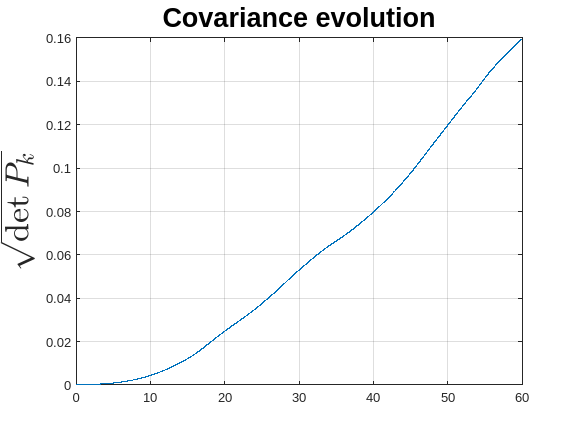

clear
close all
clf
sim("EKF_Pose_estimation_1.slx" )

## Plotting the enviroment and estimated trajectory

Attention "Do not change proces noise"  in the Simulink model: EKF_Pose_estimation_1.slx.

figure1=figure

figure1 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [671 558 577 433]
       Units: 'pixels'

  Show all properties


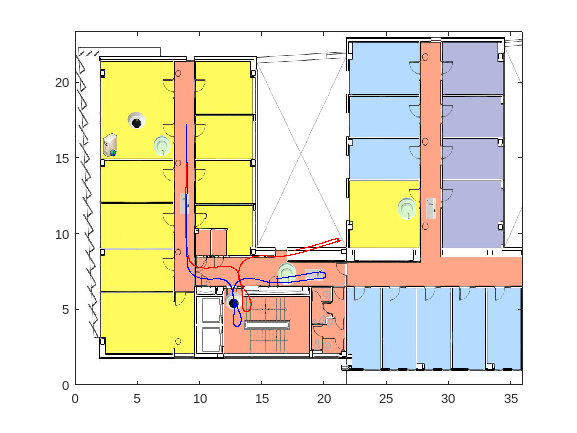

I=imread('Enviroment.png');
x_ima=[0 35.9];
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima);
axis xy
hold on
plot(Pose_est.Data(:,1),Pose_est.Data(:,2),'r')
plot(Pose_t.Data(:,1),Pose_t.Data(:,2),'b')

## Land Marks

They are known. They can be extracter from laser data, there are easy algorithms for finding they, like corner detection, etc ...

Lmk= [7.934 16.431 0 1;...
      9.583 16.431 0 1;...
      9.584 13.444 0 1;...
      9.584 10.461 0 1;...
      7.973 10.534 0 1;...
      7.934  7.547 0 1;...
      9.584  6.654 0 1;...
     13.001  6.525 0 1;...
     17.007  8.136 0 1];

### Plot Land Marks 

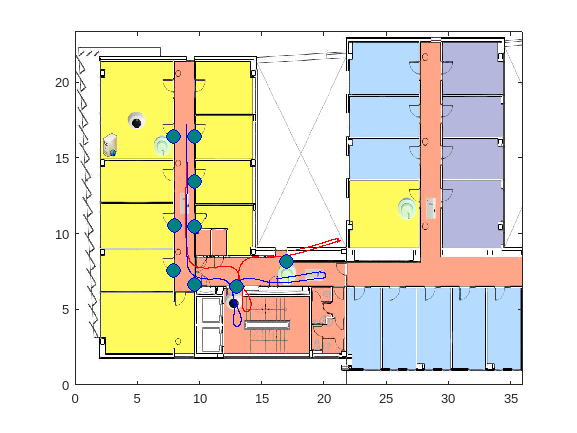

hold on
sz = 100;
s=scatter(Lmk(:,1),Lmk(:,2),sz);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];

## See an animation

Animation.mp4

### How to plot: Robot, Laser footprint and Laser beam

Declare the handler you are going  to use;

figure
hr=[]; % Robot handler
hlfp=[];% laser footprint handler
hll=[];% Laser beam handler

The Robot icon is a triangle

Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';% The Robot icon is a triangle

Laser_Range=3.9% meters

Laser_Range = 3.9000

w=linspace(-30*pi/180,210*pi/180,20); %Laser foot print
s_x=Laser_Range*sin(w);s_y=Laser_Range*cos(w);
Lfp.v=[[s_x 0];[s_y 0]]';
Lfp.f= [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 1];

Plot at origen

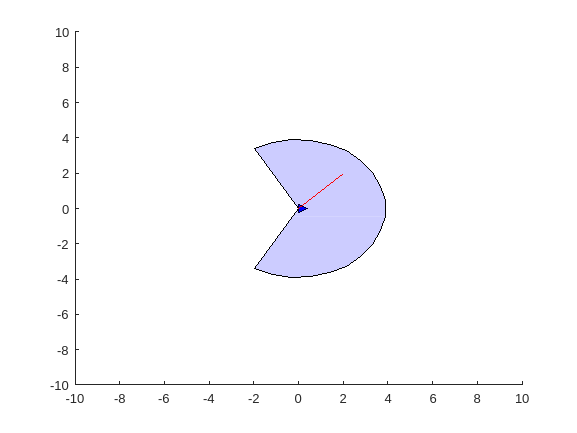

hold on
axis([-10 10 -10 10]);
Robot_tr=eye(4)*Robot; %At origen
hr=patch(Robot_tr(1,:), Robot_tr(2,:),'b');
hlfp=patch('Faces',Lfp.f,'Vertices',Lfp.v,'FaceColor','blue','FaceAlpha',.2);
hll=line([0 2],[0 2],'Color','red','LineStyle','-');

To delete

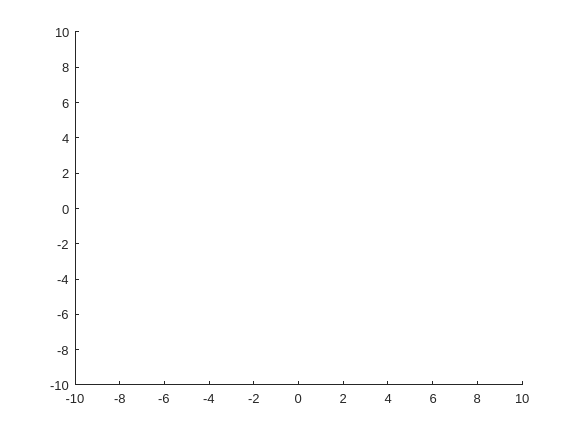

delete (hr)
delete (hlfp)
delete (hll)

## Testing Similarity Transform